## Task 2

% 2.b.
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = 1500;                            % Values for packet rate in pps
f = 10000;                                % Queue size(in bytes)
b = 10^-5;                                % Bit Error Rate

N = 20;                                   % number of simulation
n = [10, 20, 30, 40];                     % number of adidional VoIP packets flows

pkt_delay_voip = zeros(1, length(lambda));
error_delay_voip = zeros(1, length(lambda));
pkt_loss_voip = zeros(1, length(lambda)); 
error_loss_voip = zeros(1, length(lambda)); 

pkt_delay_data = zeros(1, length(lambda));
error_delay_data = zeros(1, length(lambda));
pkt_loss_data = zeros(1, length(lambda));  
error_loss_data = zeros(1, length(lambda));  

AVERAGE = zeros(4,4);
TERM = zeros(4,4);

for j = 1:length(n)
    PLd = zeros(1, N);
    PLv = zeros(1, N);
    APDd = zeros(1, N);
    APDv = zeros(1, N);
    MPDd = zeros(1, N);
    MPDv = zeros(1, N);
    TT = zeros(1, N);
    
    for i = 1:N
        [PLd(i), PLv(i), APDd(i), APDv(i), MPDd(i), MPDv(i), TT(i)] = Simulator3A(lambda,C,f,P,n(j), b);
    end    
    alfa = 0.1; % 90% confidence interval 
    
    
    AVERAGE = mean(PLd);
    TERM = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    fprintf("Packet Loss (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_data(j) = AVERAGE;
    error_loss_data(j) = TERM;

    AVERAGE = mean(APDd);
    TERM = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    fprintf("Av. Packet Delay Data (ms)  = %.2e +- %.2e\n\n\n", AVERAGE, TERM);
    pkt_delay_data(j) = AVERAGE;
    error_delay_data(j) = TERM;

    AVERAGE = mean(PLv);
    TERM = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    fprintf("Packet Loss VoIP (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_voip(j) = AVERAGE;
    error_loss_voip(j) = TERM;

    AVERAGE = mean(APDv);
    TERM = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    fprintf("Av. Packet Delay VoIP (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay_voip(j) = AVERAGE;
    error_delay_voip(j) = TERM;
 
end

Packet Loss (%)  = 4.96e+00 +- 2.70e-02


Av. Packet Delay Data (ms)  = 2.00e+00 +- 1.59e-02




Packet Loss VoIP (%)  = 9.59e-01 +- 2.82e-02


Av. Packet Delay VoIP (ms)  = 1.61e+00 +- 1.46e-02


Packet Loss (%)  = 5.12e+00 +- 4.63e-02


Av. Packet Delay Data (ms)  = 2.31e+00 +- 1.48e-02




Packet Loss VoIP (%)  = 1.01e+00 +- 1.77e-02


Av. Packet Delay VoIP (ms)  = 1.93e+00 +- 1.40e-02


Packet Loss (%)  = 5.46e+00 +- 3.65e-02


Av. Packet Delay Data (ms)  = 2.72e+00 +- 1.80e-02




Packet Loss VoIP (%)  = 1.06e+00 +- 1.64e-02


Av. Packet Delay VoIP (ms)  = 2.35e+00 +- 1.77e-02


Packet Loss (%)  = 5.99e+00 +- 5.43e-02


Av. Packet Delay Data (ms)  = 3.22e+00 +- 2.01e-02




Packet Loss VoIP (%)  = 1.13e+00 +- 1.47e-02


Av. Packet Delay VoIP (ms)  = 2.87e+00 +- 2.07e-02


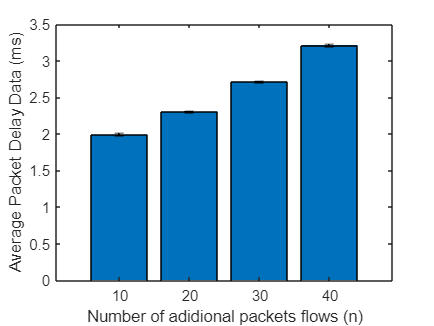



% Plot the results
figure(1)
bar(categorical(n), pkt_delay_data)
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay Data (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_data, error_delay_data, error_delay_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

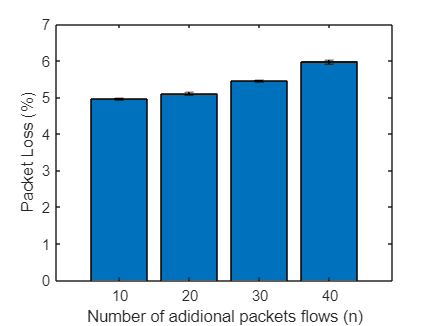


%%% Plot the results
figure(2)
bar(categorical(n), pkt_loss_data)
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_data, error_loss_data, error_loss_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

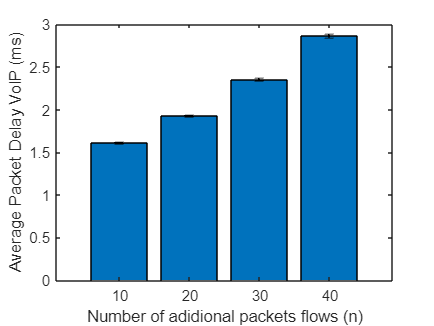


% Plot the results
figure(3)
bar(categorical(n), pkt_delay_voip)
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay VoIP (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_voip, error_delay_voip, error_delay_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

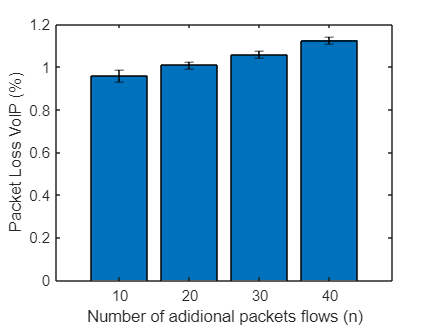


%%% Plot the results
figure(4)
bar(categorical(n), pkt_loss_voip)
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss VoIP (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_voip, error_loss_voip, error_loss_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;